# META 2

%% Meta 2: Processamento Espectral


## 10


% Carregamento da estrutura de dados ---
load('AED1.mat');  % A variável 'tab' deve estar presente


## 11

% Número de arquivos (linhas da tabela)
nArquivos = height(tab);

%--- Verifica se o campo FourierCoeffs existe e se é um cell array ---
if ~isfield(tab, 'FourierCoeffs') || ~iscell(tab.FourierCoeffs)
    % Se não existir ou não for cell, cria um cell array do tamanho correto
    tab.FourierCoeffs = cell(nArquivos,1);
end

%% Exercício 11: Cálculo dos Coeficientes da Série Complexa de Fourier
for i = 1:nArquivos
    s = tab.Sinal_Processado{i};  % Recupera o sinal processado
    tab.FourierCoeffs{i} = fft(s);  % Calcula e armazena os coeficientes
end

% Salva a tabela atualizada
save('AED1.mat', 'tab');
disp(tab);

                        Diretorio_Audio                         Nome_Arquivo      Digito    Participante    Repeticao    Sinal_Processado    Taxa_Amostragem    EnergiaTotal    EnergiaPrimeiraMetade    EnergiaSegundaMetade    DesvioPadraoAmplitude      RMS      MediaAmplitude    FatorCrest    TaxaCruzamento     FourierCoeffs      SpecMaxAmp    SpecMaxFreq    SpecCentroid    SpecEdgeFreq    SpecBandwidth    MaxSpecAmp    MaxSpecFreq    SpectralCentroid    SpectralEdgeFreq    SpectralBandwidth
    __________________________________________________

## 12

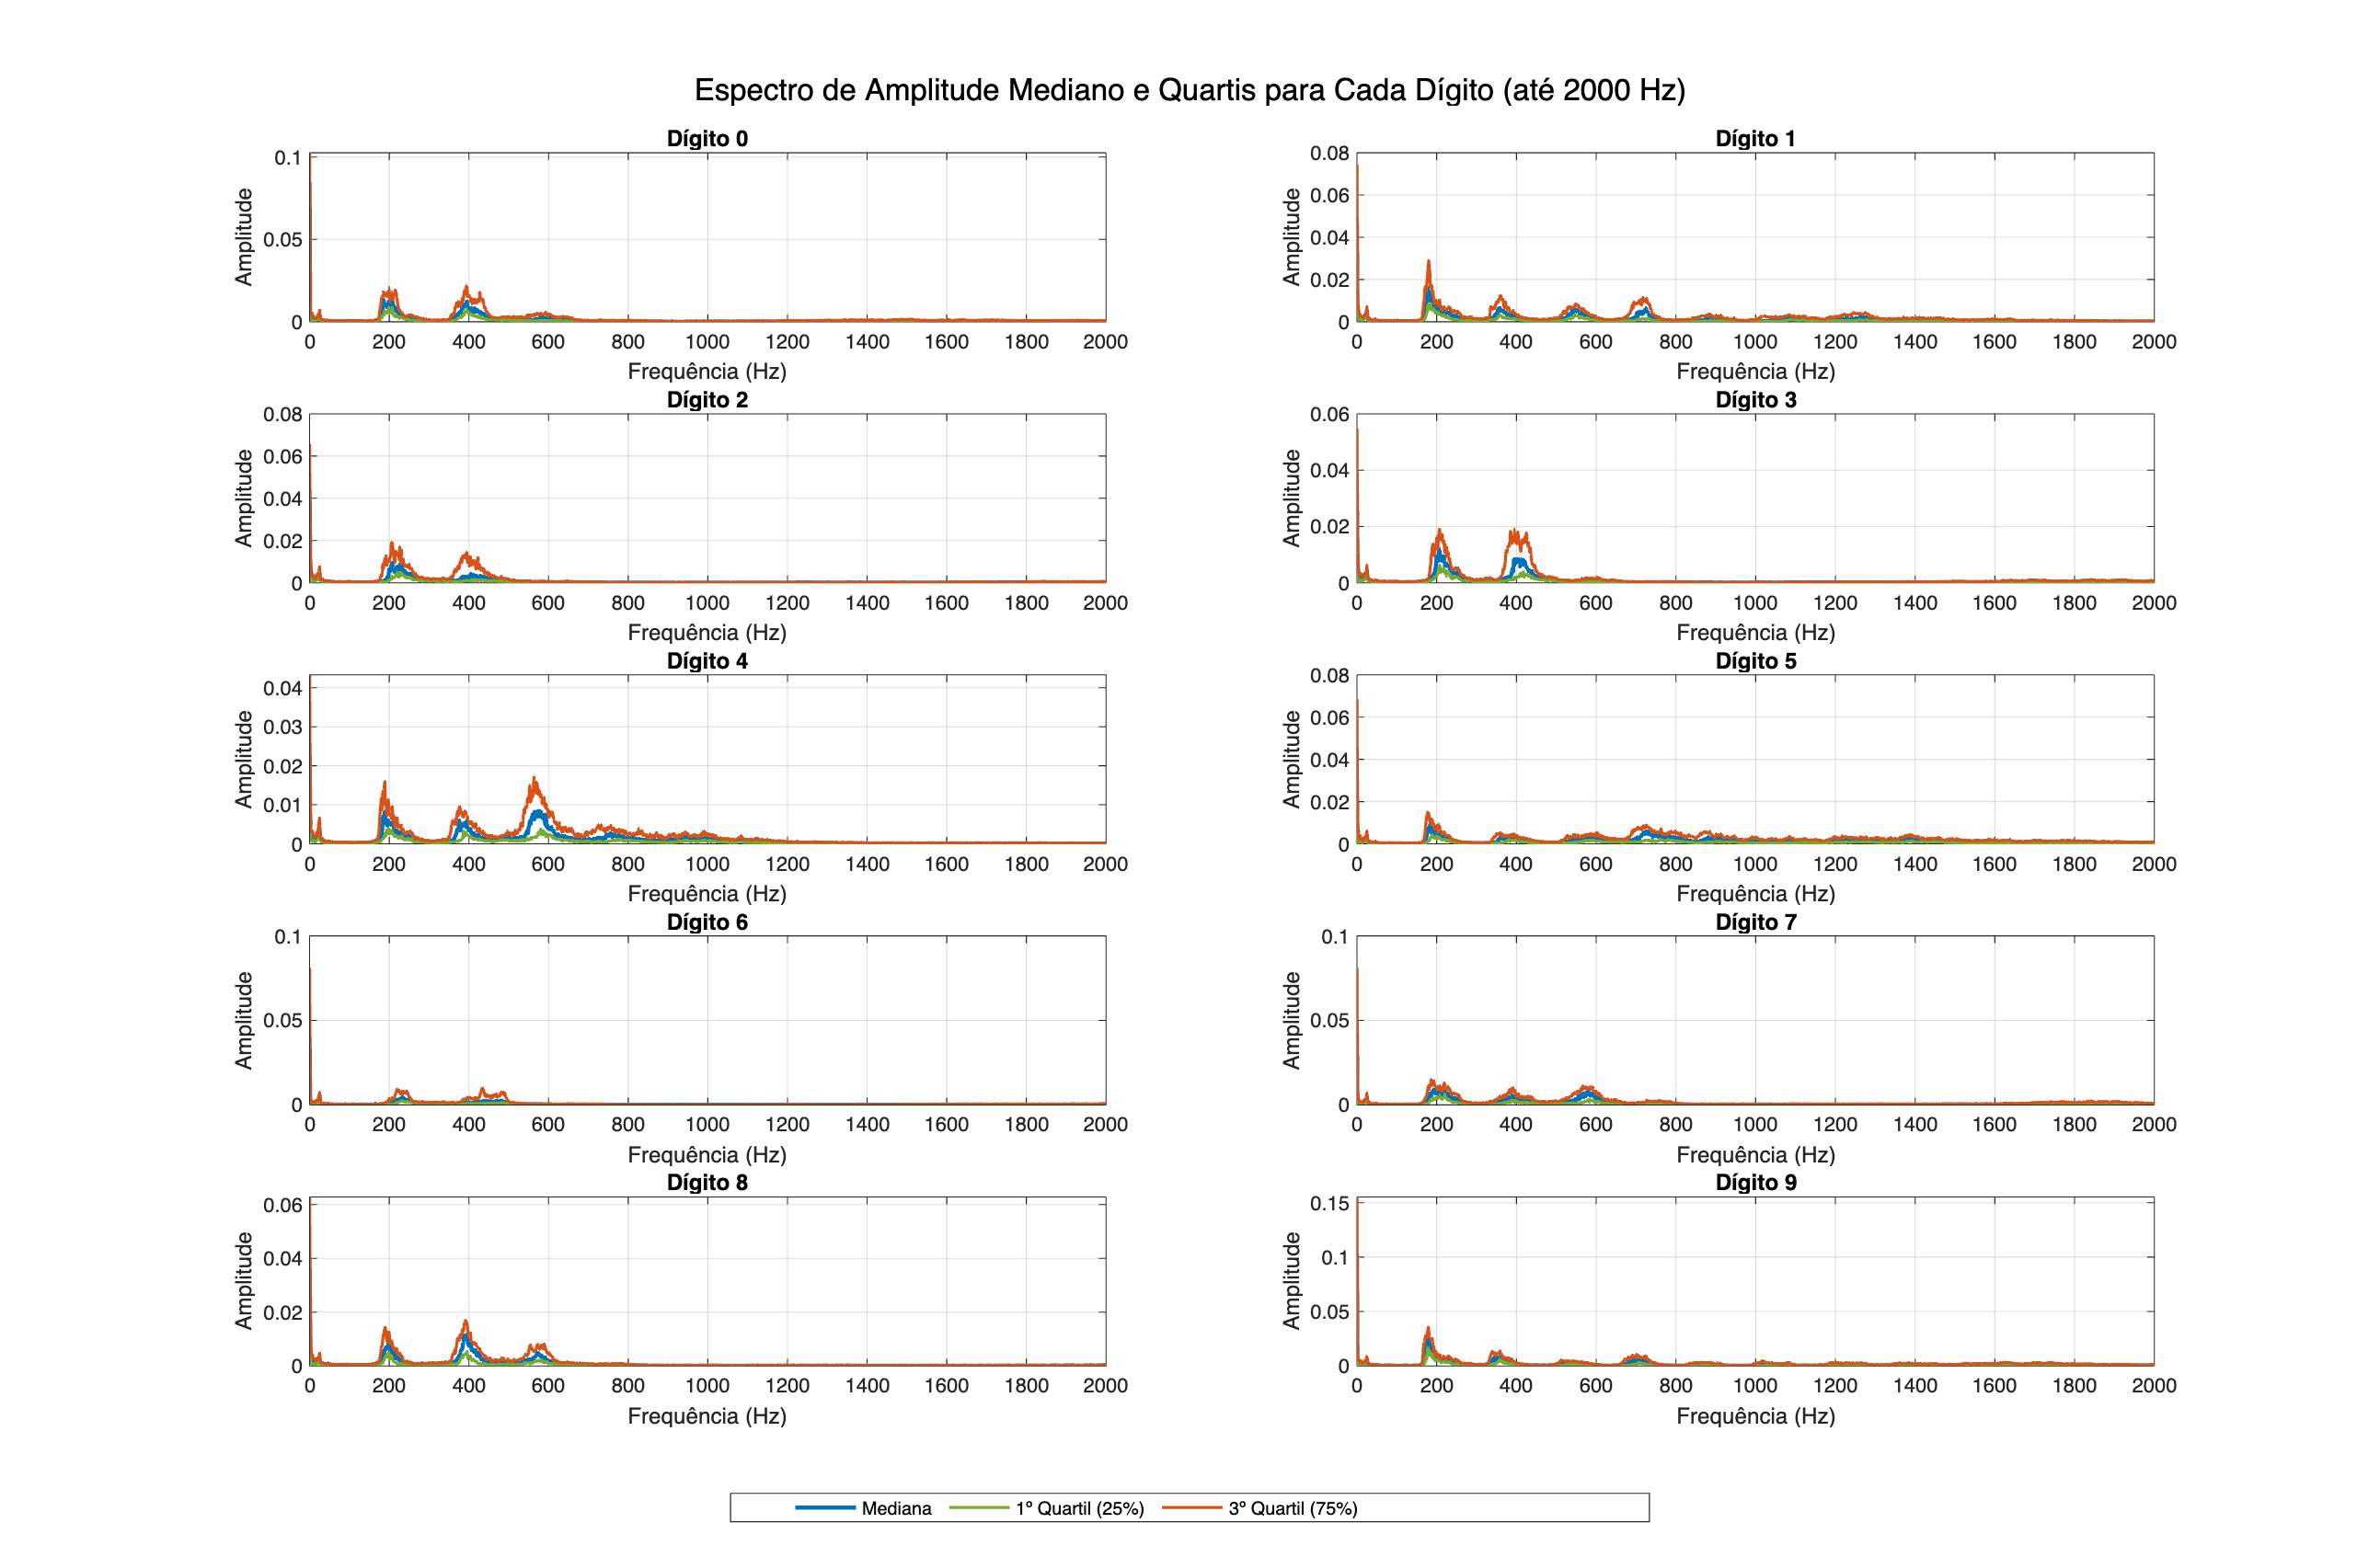


% Cálculo e Visualização do Espectro de Amplitude Mediano e Quartis (até 2000 Hz)
% Identifica os dígitos únicos
digitosUnicos = unique(tab.Digito);
numDigitos = numel(digitosUnicos);

figure('Name', 'Espectro de Amplitude Mediano e Quartis por Dígito', ...
       'Units','normalized','OuterPosition',[0 0 1 1]);

% Handles para legenda do primeiro subplot
hMed = []; hQ1 = []; hQ3 = [];

for k = 1:numDigitos
    digitoAtual = digitosUnicos(k);
    idx = find(tab.Digito == digitoAtual);
    numSinais = numel(idx);
    
    % Utiliza o primeiro sinal para obter a taxa de amostragem e tamanho do sinal
    s_exemplo = tab.Sinal_Processado{idx(1)};
    fs = tab.Taxa_Amostragem(idx(1));
    N = length(s_exemplo);
    
    % Índices para frequências positivas
    posIdx = 1:floor(N/2)+1;
    f = (posIdx - 1) * fs / N;
    
    % Seleciona apenas as frequências até 2000 Hz
    cutoffIdx = find(f <= 2000);
    f_cut = f(cutoffIdx);
    
    % Prealoca a matriz para armazenar os espectros de amplitude
    espectros = zeros(length(cutoffIdx), numSinais);
    for j = 1:numSinais
        s = tab.Sinal_Processado{idx(j)};
        fftS = fft(s) / N;                % FFT normalizada pelo número de amostras
        spec = abs(fftS(posIdx));           % Espectro para frequências positivas
        espectros(:, j) = spec(cutoffIdx);
    end
    
    % Calcula a mediana, 1º quartil (25%) e 3º quartil (75%) para cada frequência
    mediano = median(espectros, 2);
    q1 = quantile(espectros, 0.25, 2);
    q3 = quantile(espectros, 0.75, 2);
    
    subplot(ceil(numDigitos / 2), 2, k);
    % Alteradas as cores para melhor distinção:
    h1 = plot(f_cut, mediano, 'Color', [0 0.4470 0.7410], 'LineWidth', 2); hold on;
    h2 = plot(f_cut, q1, 'Color', [0.4660 0.6740 0.1880], 'LineWidth', 1.5);
    h3 = plot(f_cut, q3, 'Color', [0.8500 0.3250 0.0980], 'LineWidth', 1.5);
    hold off;
    
    xlabel('Frequência (Hz)');
    ylabel('Amplitude');
    title(sprintf('Dígito %d', digitoAtual));
    grid on;
    
    % Guarda os handles do primeiro subplot para legenda
    if k == 1
        hMed = h1;
        hQ1 = h2;
        hQ3 = h3;
    end
end

% Cria uma legenda comum para todos os subplots, posicionada na parte inferior
legend([hMed, hQ1, hQ3], {'Mediana','1º Quartil (25%)','3º Quartil (75%)'}, ...
       'Orientation', 'horizontal', 'Position', [0.35 0.01 0.3 0.03]);

sgtitle('Espectro de Amplitude Mediano e Quartis para Cada Dígito (até 2000 Hz)');

## 13

% Pre-aloca os vetores de características (garante que sejam colunas de tamanho nArquivos)
MaxSpecAmp        = zeros(nArquivos, 1);
MaxSpecFreq       = zeros(nArquivos, 1);
SpectralCentroid  = zeros(nArquivos, 1);
SpectralEdgeFreq  = zeros(nArquivos, 1);
SpectralBandwidth = zeros(nArquivos, 1);

for i = 1:nArquivos
    signal = tab.Sinal_Processado{i};
    if isempty(signal)
        continue;
    end
    
    N = length(signal);
    fs = tab.Taxa_Amostragem(i);
    Y = fft(signal);
    magSpec = abs(Y) / N;
    
    % Considera somente as frequências positivas
    posFreqCount = floor(N/2) + 1;
    magSpec = magSpec(1:posFreqCount);
    f = linspace(0, fs/2, posFreqCount)';
    
    % 1. Amplitude Espectral Máxima e a frequência correspondente
    [maxAmp, idxMax] = max(magSpec);
    MaxSpecAmp(i) = maxAmp;
    MaxSpecFreq(i) = f(idxMax);
    
    % 2. Centroide Espectral (média ponderada das frequências)
    if sum(magSpec) > 0
        SpectralCentroid(i) = sum(f .* magSpec) / sum(magSpec);
    else
        SpectralCentroid(i) = 0;
    end
    
    % 3. Frequência de Borda Espectral (frequência abaixo da qual 90% da energia está contida)
    cumulativeEnergy = cumsum(magSpec);
    totalEnergy = cumulativeEnergy(end);
    idxEdge = find(cumulativeEnergy >= 0.9 * totalEnergy, 1);
    SpectralEdgeFreq(i) = f(idxEdge);
    
    % 4. Largura de Banda Espectral (desvio padrão das frequências ponderado pelo espectro)
    if sum(magSpec) > 0
        SpectralBandwidth(i) = sqrt(sum(((f - SpectralCentroid(i)).^2) .* magSpec) / sum(magSpec));
    else
        SpectralBandwidth(i) = 0;
    end
end

% Atualiza a estrutura de dados com as novas características espectrais
tab.MaxSpecAmp = MaxSpecAmp;
tab.MaxSpecFreq = MaxSpecFreq;
tab.SpectralCentroid = SpectralCentroid;
tab.SpectralEdgeFreq = SpectralEdgeFreq;
tab.SpectralBandwidth = SpectralBandwidth;

% Exibe a tabela atualizada e salva em arquivo
disp(tab)

                        Diretorio_Audio                         Nome_Arquivo      Digito    Participante    Repeticao    Sinal_Processado    Taxa_Amostragem    EnergiaTotal    EnergiaPrimeiraMetade    EnergiaSegundaMetade    DesvioPadraoAmplitude      RMS      MediaAmplitude    FatorCrest    TaxaCruzamento     FourierCoeffs      SpecMaxAmp    SpecMaxFreq    SpecCentroid    SpecEdgeFreq    SpecBandwidth    MaxSpecAmp    MaxSpecFreq    SpectralCentroid    SpectralEdgeFreq    SpectralBandwidth
    __________________________________________________

## 14

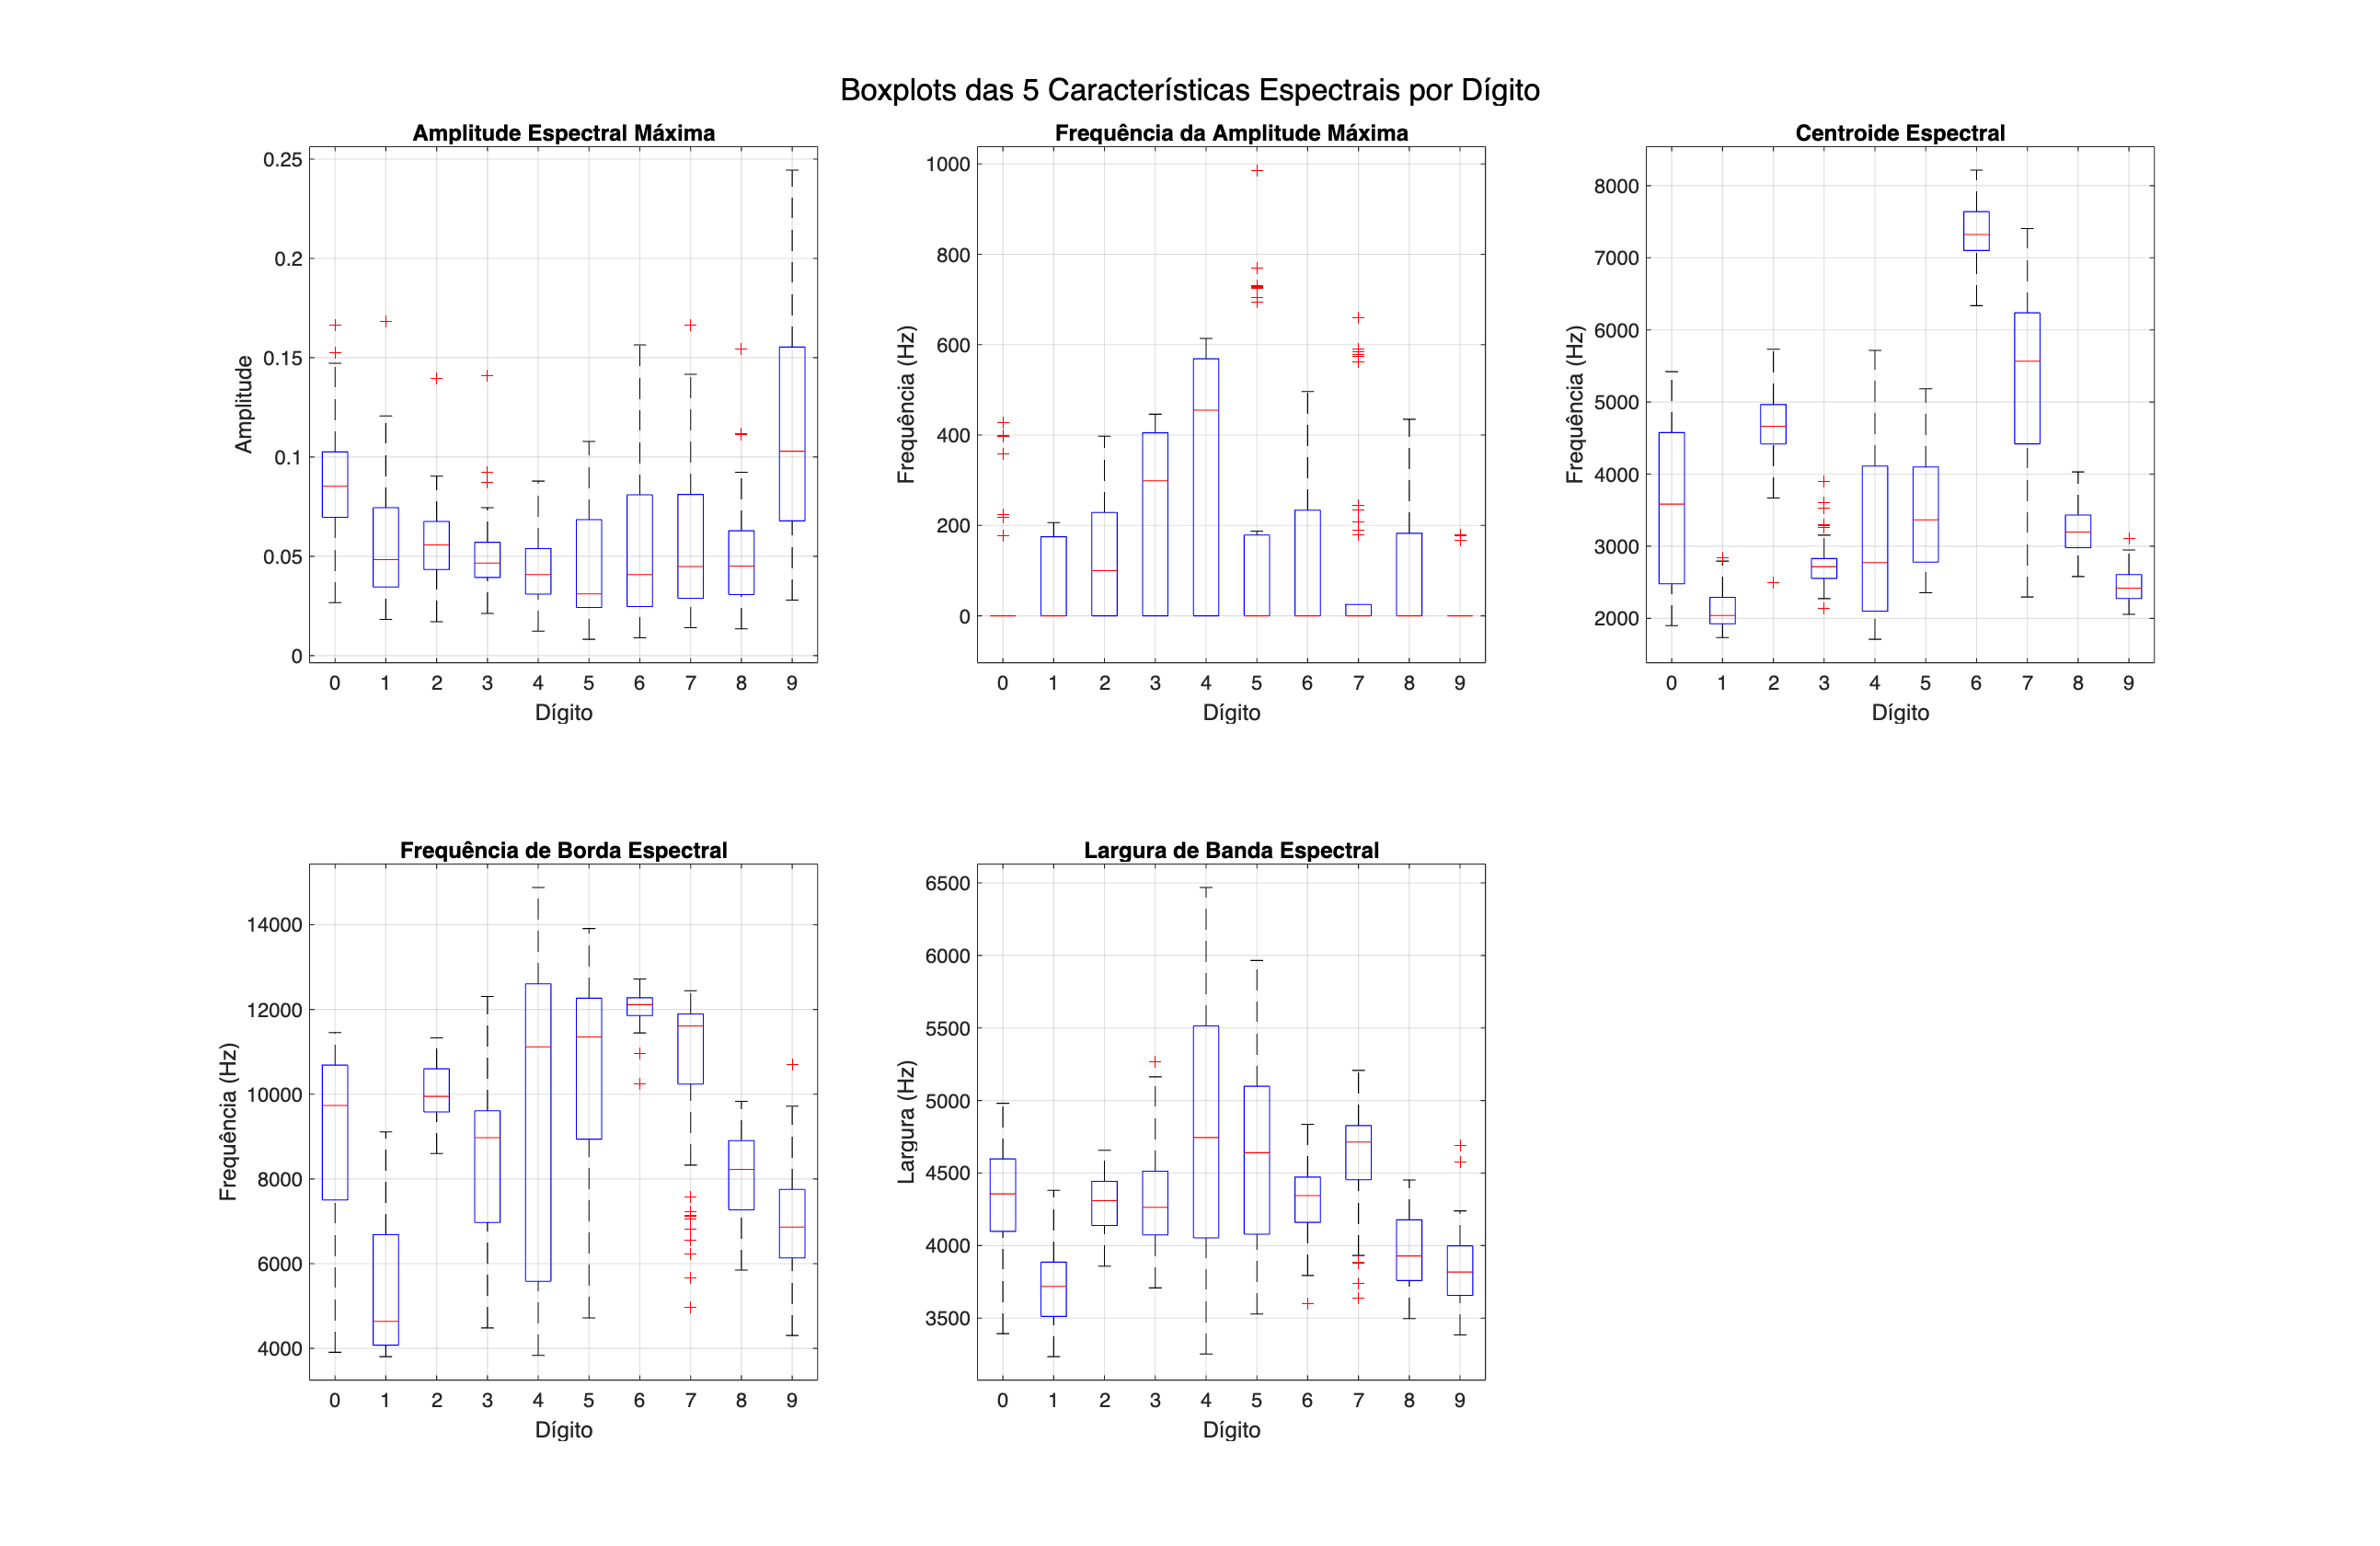

figure('Name','Boxplots das 5 Características Espectrais por Dígito','Units','normalized','OuterPosition',[0 0 1 1]);

% Boxplot para MaxSpecAmp (Amplitude Espectral Máxima)
subplot(2,3,1);
boxplot(tab.MaxSpecAmp, tab.Digito);
xlabel('Dígito');
ylabel('Amplitude');
title('Amplitude Espectral Máxima');
grid on;

% Boxplot para MaxSpecFreq (Frequência da Amplitude Máxima)
subplot(2,3,2);
boxplot(tab.MaxSpecFreq, tab.Digito);
xlabel('Dígito');
ylabel('Frequência (Hz)');
title('Frequência da Amplitude Máxima');
grid on;

% Boxplot para SpectralCentroid (Centroide Espectral)
subplot(2,3,3);
boxplot(tab.SpectralCentroid, tab.Digito);
xlabel('Dígito');
ylabel('Frequência (Hz)');
title('Centroide Espectral');
grid on;

% Boxplot para SpectralEdgeFreq (Frequência de Borda Espectral)
subplot(2,3,4);
boxplot(tab.SpectralEdgeFreq, tab.Digito);
xlabel('Dígito');
ylabel('Frequência (Hz)');
title('Frequência de Borda Espectral');
grid on;

% Boxplot para SpectralBandwidth (Largura de Banda Espectral)
subplot(2,3,5);
boxplot(tab.SpectralBandwidth, tab.Digito);
xlabel('Dígito');
ylabel('Largura (Hz)');
title('Largura de Banda Espectral');
grid on;

sgtitle('Boxplots das 5 Características Espectrais por Dígito');

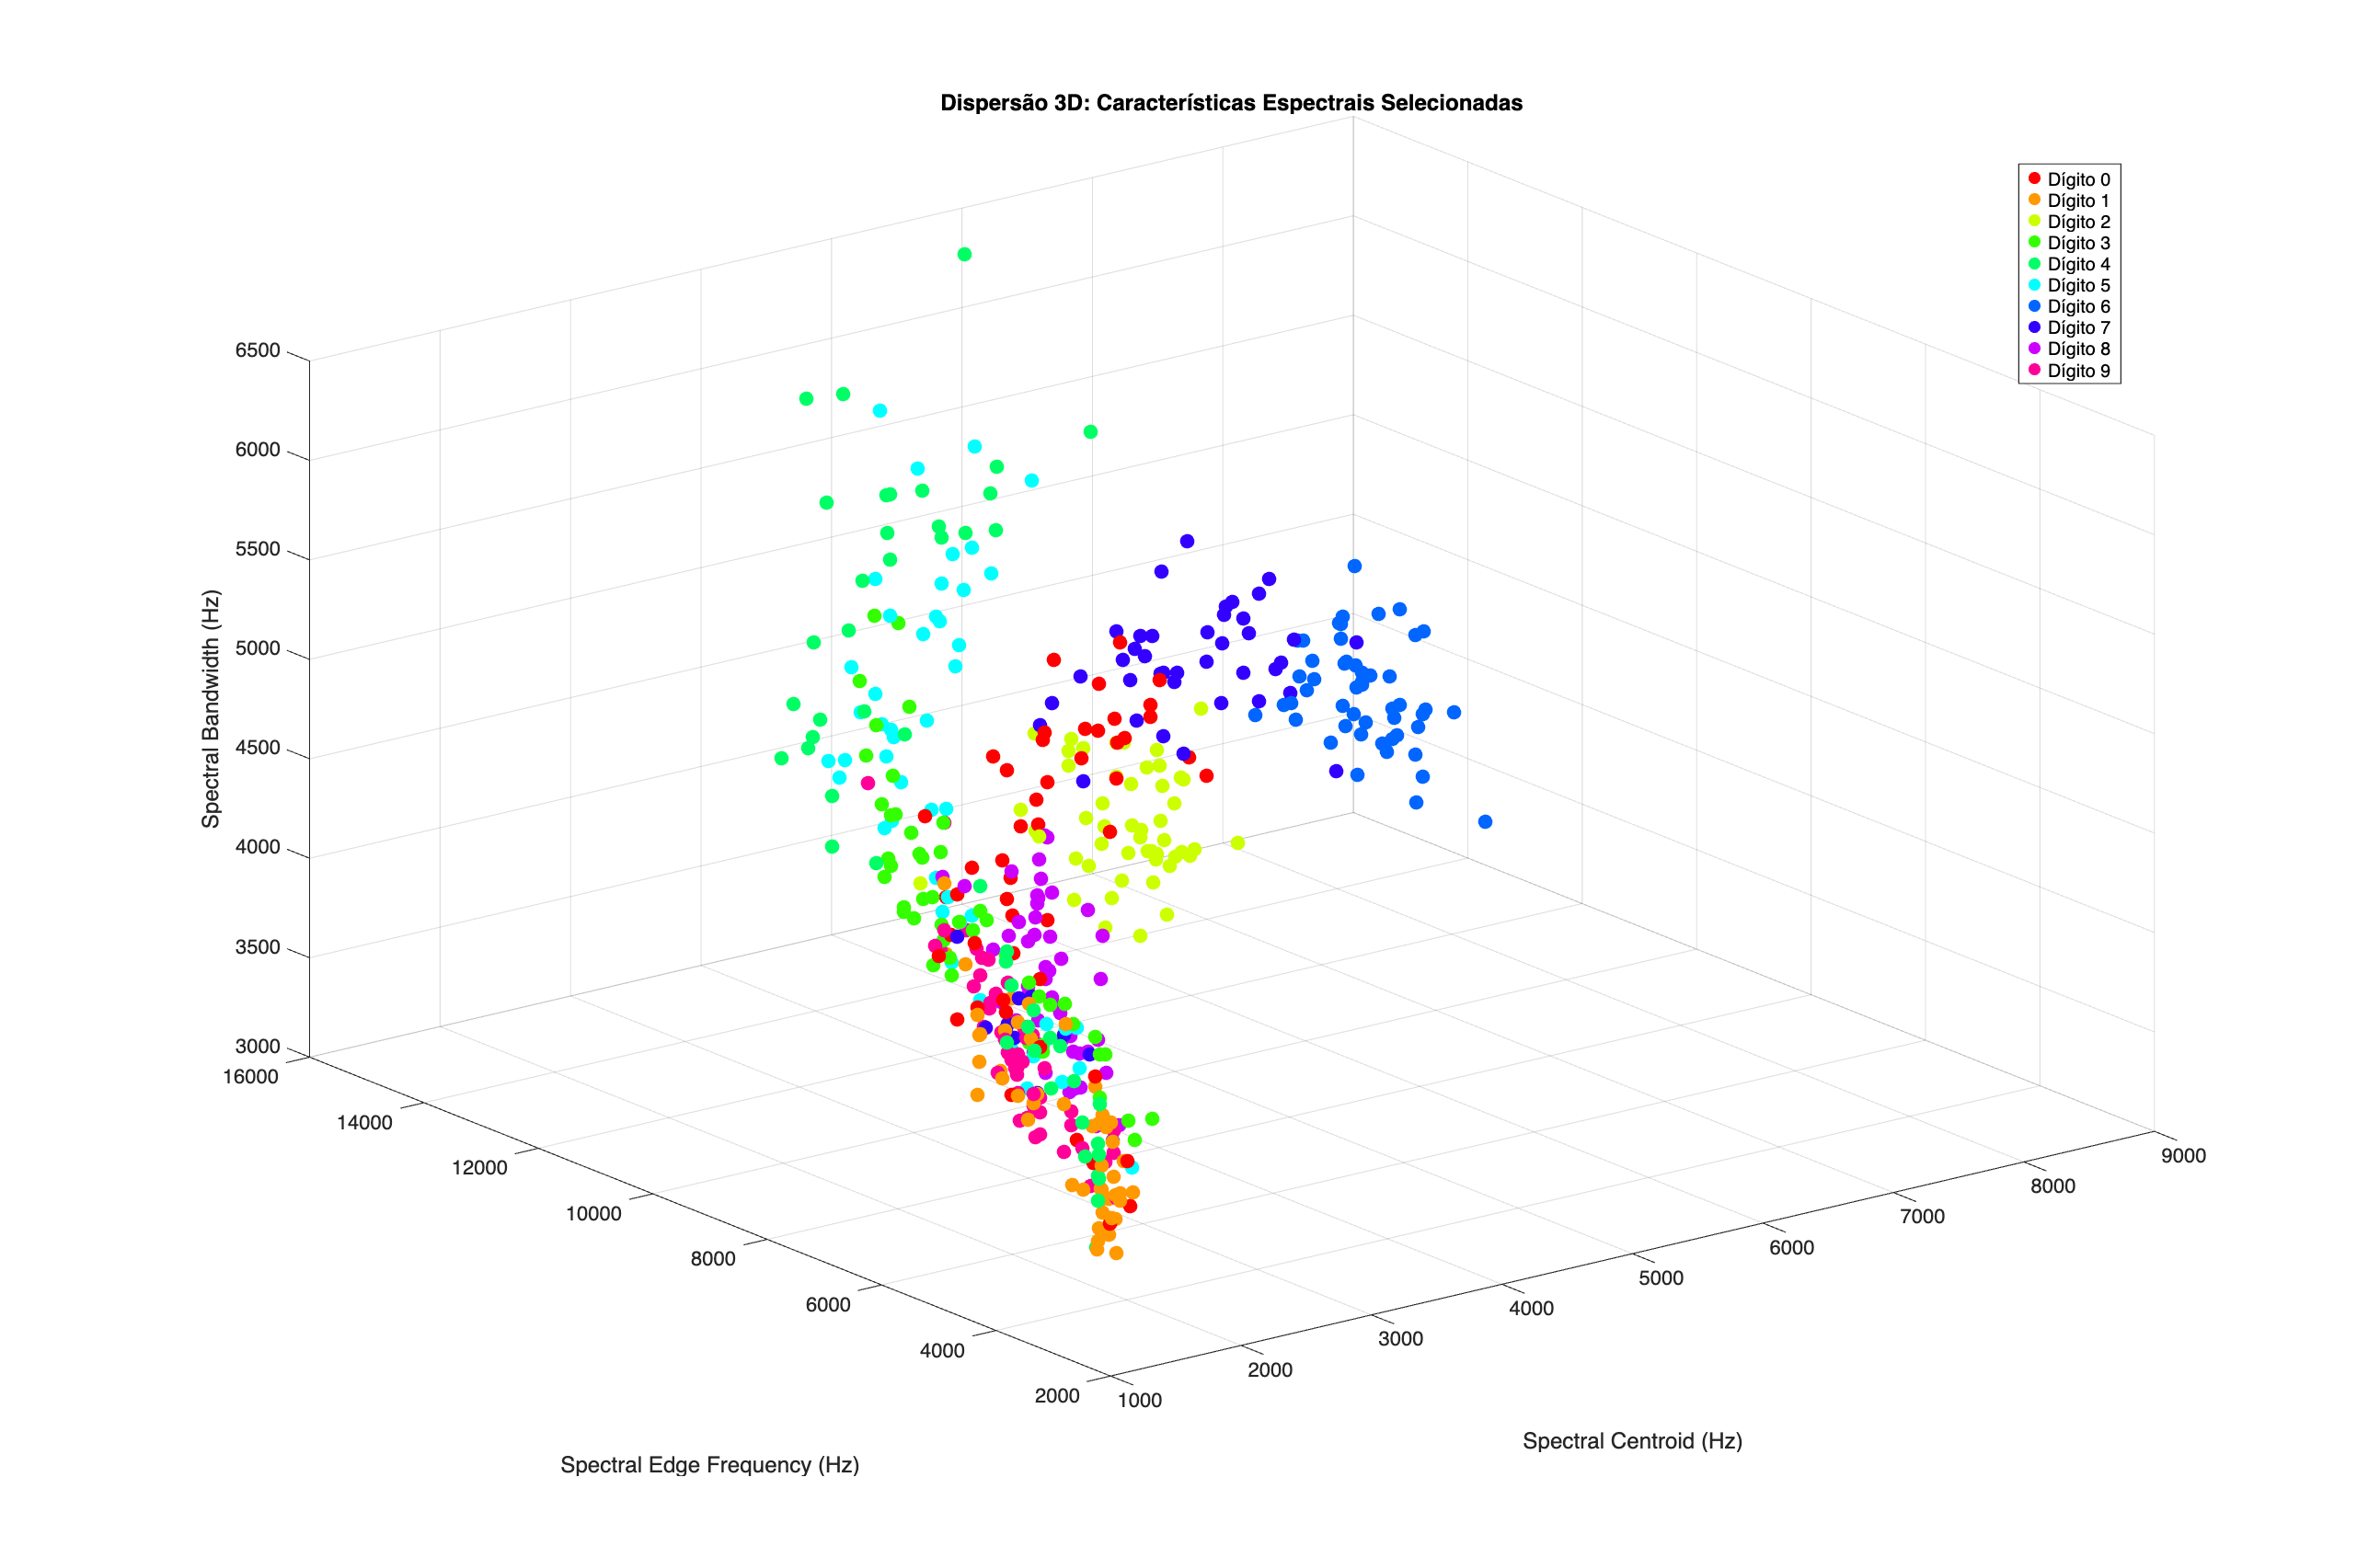



figure('Name','Dispersão 3D: Características Espectrais Selecionadas','Units','normalized','OuterPosition',[0 0 1 1]);
uniqueDigits = unique(tab.Digito);
numDigits = numel(uniqueDigits);
cores = hsv(numDigits);

hold on;
scatterHandles = gobjects(numDigits,1);
for k = 1:numDigits
    idx = (tab.Digito == uniqueDigits(k));
    scatterHandles(k) = scatter3(tab.SpectralCentroid(idx), tab.SpectralEdgeFreq(idx), tab.SpectralBandwidth(idx), 50, cores(k,:), 'filled');
end
hold off;

xlabel('Spectral Centroid (Hz)');
ylabel('Spectral Edge Frequency (Hz)');
zlabel('Spectral Bandwidth (Hz)');
title('Dispersão 3D: Características Espectrais Selecionadas');
grid on;
view(3); % Garante a visualização 3D

legendEntries = arrayfun(@(d) sprintf('Dígito %d', d), uniqueDigits, 'UniformOutput', false);
legend(scatterHandles, legendEntries, 'Location', 'best');





% 3. Comentário:
% Após analisar os gráficos, observa-se que as características "SpectralCentroid",
% "SpectralEdgeFreq" e "SpectralBandwidth" demonstram boa separação entre os dígitos.
% Portanto, elas foram escolhidas como as três características que permitem melhor
% discriminação dos dígitos.


## 15

save('AED1.mat', 'tab');
